# Practice of robot system toolbox with visulization

Peter Chang 2026/01/22

Example of using DH (standard) to build rigid body tree, also practice from "learning_jackobian" exercise

## Spong's book Example 3.2 Cylindrical Robot base to arm no wrist definition

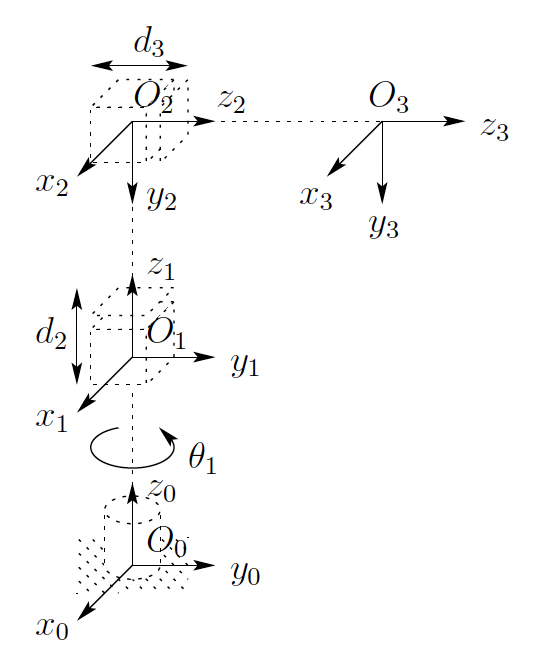

assume that a resonable table-top arm setup, the d-h table from the previous frame assignment shows: c means constant

this meant there are three rigid bodies: link1-revolute, link2-prismatic, link3-prismatic. R-P-P setup.

Asked ChatGPT to learn later assignement on future mass, moment of inertia, center of mass and "geometry" so on.

Now needs to focus on rigid body tree object usage and definition.

% comparison of MATLAB code and Craig's code
% using matlab robotics toolbox to create a rotbot (rigid body tree) object
% recall matlab document: https://www.mathworks.com/help/robotics/ug/build-manipulator-robot-using-kinematic-dh-parameters.html

close all;
clear;
clc

First learn to use rigid body for slow process and test Transform


$$^{parent}T_{child}(q) = ^{parent}T_{joint}\; \underbrace{T_{\text{motion}}(q)}_{\text{about JointAxis}}\; ^{joint}T_{child}$$


% body1 = rigidBody('body1')
% 
% jnt1 = rigidBodyJoint('jnt1','revolute')
% jnt1.HomePosition = pi/4;
% tform = trvec2tform([0.25, 0.25, 0]); % User defined
% setFixedTransform(jnt1,tform);
% body1.Joint = jnt1
% jnt1
% jnt1.JointToParentTransform
% jnt1.ChildToJointTransform

Now there is a joint axis property, and thus the most important part is that where the "joint axis" (always set as [0 0 1] the "imaginary z axis" is located, oriented (!Joint frame!) relatively to the "parent frame". This makes the imaginary rigid body a joint that is either "fliped/twisted" against the previous frame, and relaxing the variable of "prismatic", "revolute" into a random rotation/elongation number in matlab show(robot).

% pre-assign 
th1 = 0;
d2 = .0; 
d3 = .0;

dhparams = [0 0 0.2 th1;0 -deg2rad(90) 0.2+d2 0;0 0 0.2+d3 0]

dhparams =          0         0    0.2000         0
         0   -1.5708    0.2000         0
         0         0    0.2000         0



[nrow ncol] = size(dhparams);
% create robot tree object
cy_robot = rigidBodyTree;

% Using cell array for rigid body object, another for joint object.
bodies = cell(nrow,1);
joints = cell(nrow,1);

    bodies{1} = rigidBody(['body' num2str(1)]);
    bodies{2} = rigidBody(['body' num2str(2)]);
    bodies{3} = rigidBody(['body' num2str(3)]);

    joints{1} = rigidBodyJoint(['jnt' num2str(1)],"revolute");
    joints{2} = rigidBodyJoint(['jnt' num2str(2)],"prismatic");
    joints{3} = rigidBodyJoint(['jnt' num2str(3)],"prismatic");

First assign all the body names, and the joint names. This is essential that how to dirve all the joints kinematics, later for speed/jacobian and then dynamics. Note joints always move on local [0 0 1] z-axis, with revolute/rotation, and presimatic/elongation either direction.

% iterate through dhparams to put in the cell array
for i = 1:nrow
    setFixedTransform(joints{i}, dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};    % don't forget this part!!!
    if i == 1 % add first body to base
        addBody(cy_robot,bodies{i},"base")
    else
        addBody(cy_robot,bodies{i},bodies{i-1}.Name)
    end
end

This is the standard way to attach all bodies by 1. setFixedTransform(jointObj, tform). Remeber jointObj is which joint to be "jointToParent" frame (tform) Transformation, setting joint position/orientation (at end of link), relative to the parent (so the last link/joint also at parent link)'s frame. 2. can also do setFixedTransform(jointObj, dpparams, "dh") or setFixedTransform(jointObj, mdpparams, "mdh") for both standard DH (Spong) or modified DH (Craig). 

3. Most important, the book keeping of all the frame {i}, is the user's job, and to follow all the co-incidal orgins as using dh, mdh setFixedTransform is going to "ignore" the parameterized movement (\theta for revolute, d for prismatic). 

showdetails(cy_robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   
--------------------


this command is for assuring all bodies and joints are attached in order.

% figure(Name="Plannar model")
% show(robot)
fig = figure('Name',"Cylindrical Robot", 'NumberTitle','off', 'WindowStyle','normal');
ax = axes('Parent',fig);
figure(fig);

sure way to add a un-embedded figure frame outside of matlab windows gui, and fill both figures..

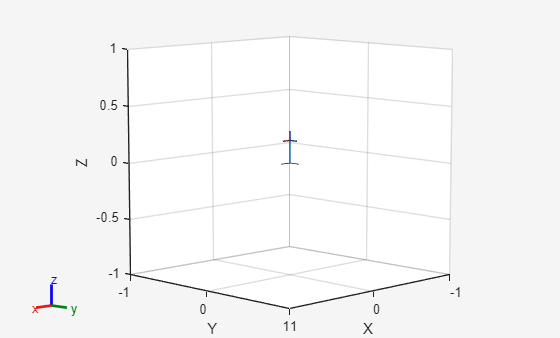

show(cy_robot, 'Parent',ax,"Frames","on");
axis(ax,"equal");
grid(ax,"on");
rotate3d(fig,'on');

drawnow;

a short snippet for acquireing "q" to get current home configuration of the current body's all frame location and orientation.

q = homeConfiguration(cy_robot);

for name = ["body1","body2","body3"]
    T = getTransform(cy_robot, q, name);
    p = tform2trvec(T);
    rpy = tform2eul(T, "XYZ");   % roll-pitch-yaw (radians)
    fprintf("%s origin = [%.4f %.4f %.4f]\n", name, p(1), p(2), p(3));
    fprintf("%s direction = [%.4f %.4f %.4f]\n", name, rpy(1), rpy(2), rpy(3));
end

body1 origin = [0.0000 0.0000 0.2000]


body1 direction = [-0.0000 0.0000 -0.0000]


body2 origin = [0.0000 0.0000 0.2000]


body2 direction = [-1.5708 0.0000 -0.0000]


body3 origin = [0.0000 0.0000 0.2000]


body3 direction = [-1.5708 0.0000 -0.0000]


special way to add a new figure to move and check the degree of freedom, and move the end effector to show fk/ik, with limited workspace movement.

% figure(Name="Interactive GUI")
% gui = interactiveRigidBodyTree(cy_robot,MarkerScaleFactor=0.5);

Right now this shows a little strange as the three default \theta_a, d_2 and d_3 are all zero but moveable. We need to manyully move (type in a number) them and update the new robot to show all the frames!!

% check q
whos q

  Name      Size            Bytes  Class     Attributes

  q         1x3               822  struct              



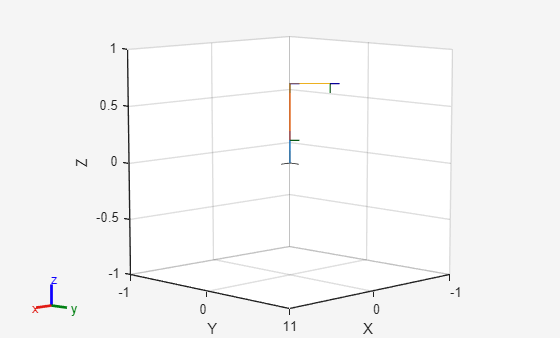

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


q(1).JointPosition = pi/4;
q(2).JointPosition = .5;
q(3).JointPosition = 0.35;

show(cy_robot, q,"Frames","on")

This is how to continously move into the joints, imaging giving timed command and draw window by window.

Using a circle path trajectory (so that the velocity is also continous) in work space, starting point on the radius that is pre-assigned, no need to move to the circle. Using sin/cos and directly the inverse kinematics to pre-assign the location!

clc;
clear all;
close all;

% New z-planar mDH table using craig's example, for a 2-link robot.
t =linspace(0,10,10001);    % total simulation of 10 seconds, SR 1000 hz, ST 1ms.

f = 1;      % 1 hz (one cycle per second, 1 rps = 60 rpm) likly 10 revolutions

v = sin(2*pi*f*t);   % set velocity at 10 cm/s, so it is a constant velocity using sine

fig = figure('Name',"Velocity assigment");

fig =   Figure (1: Velocity assigment) with properties:

      Number: 1
        Name: 'Velocity assigment'
       Color: [0.9608 0.9608 0.9608]
    Position: [242 118 560 337.4088]
       Units: 'pixels'

  Show all properties


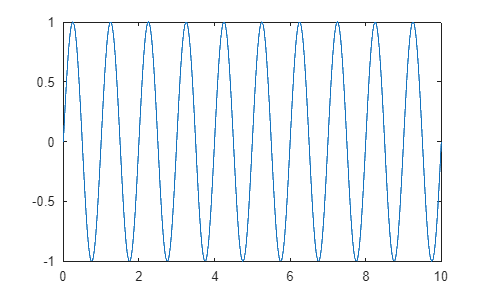

ax =   Line with properties:

              Color: [0.0660 0.4430 0.7450]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1.0000e-03 0.0020 0.0030 0.0040 0.0050 0.0060 0.0070 0.0080 0.0090 0.0100 0.0110 0.0120 0.0130 0.0140 0.0150 0.0160 0.0170 0.0180 0.0190 0.0200 0.0210 0.0220 0.0230 0.0240 0.0250 0.0260 0.0270 0.0280 0.0290 … ] (1×10001 double)
              YData: [0 0.0063 0.0126 0.0188 0.0251 0.0314 0.0377 0.0440 0.0502 0.0565 0.0628 0.0691 0.0753 0.0816 0.0879 0.0941 0.1004 0.1066 0.1129 0.1191 0.1253 0.1316 0.1378 0.1440 0.1502 0.1564 0.1626 0.1688 0.1750 0.1812 0.1874 … ] (1×10001 double)

  Show 

ax = plot(t,v);